clc;clear;
load Q.mat 
X = 1:length(Q)

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


mdl = fitlm(X, Q)

mdl = 线性回归模型:
    y ~ 1 + x1

估计系数:
                   Estimate        SE         tStat     pValue
                   ________    __________    _______    ______

    (Intercept)    -42.448        0.12578    -337.47      0   
    x1             0.13705     2.5098e-06      54606      0   


观测值数目: 86806，误差自由度: 86804
均方根误差: 18.5
R 方: 1，调整 R 方 1
F 统计量(常量模型): 2.98e+09，p 值 = 0

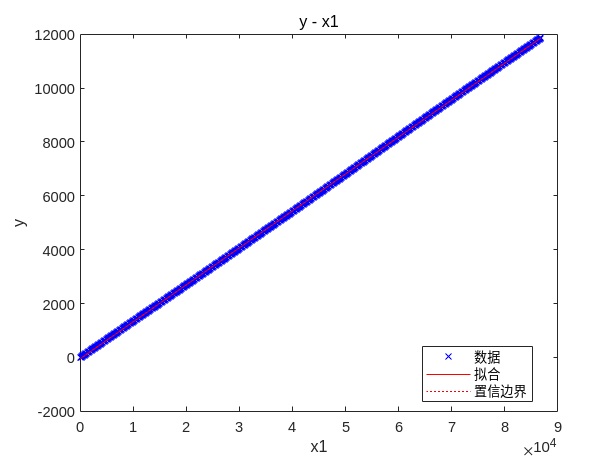


figure 
% plot(Q(1:10000))
% hold on
plot(mdl)
hold on

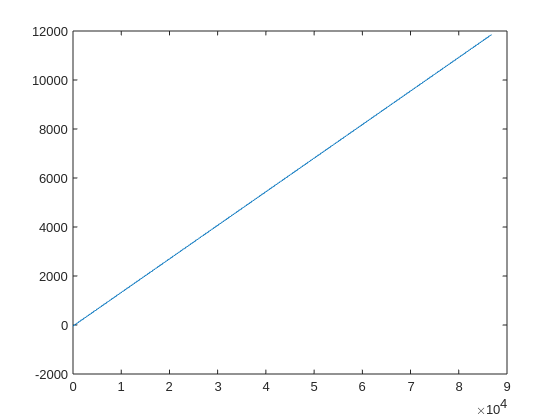


Y = 0.13705 * X - 42.448;
figure 
plot(X, Y)
hold on